## **Notes for the design of fsdz code**

### drgCaImAn_pre_per_to_LDA_fsdz

This script uses the data in pre_per files to do a decoding analysis.

drgCaImAn_pre_per_to_LDA_fsdz was updated to be able to analyze multiple files for each mouse per odor pair. Below are two files used to test this version of the code.

First I run each separately:

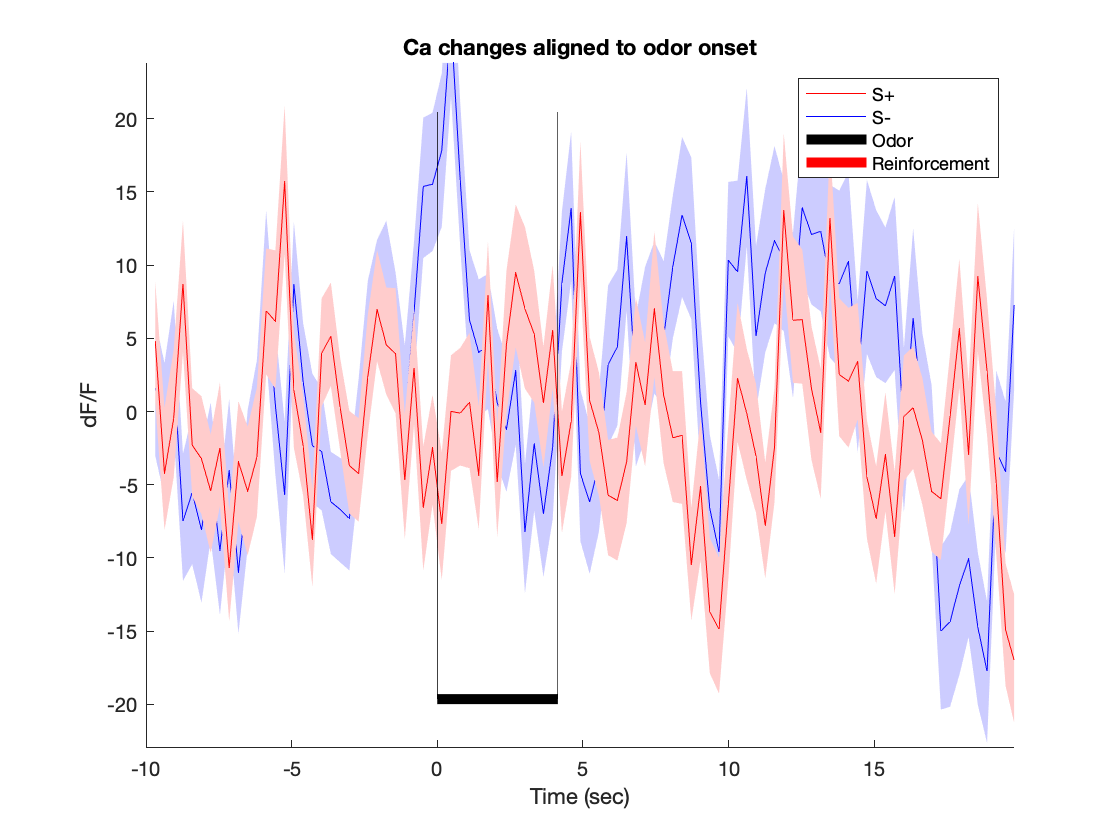

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 7
              Cluster: 

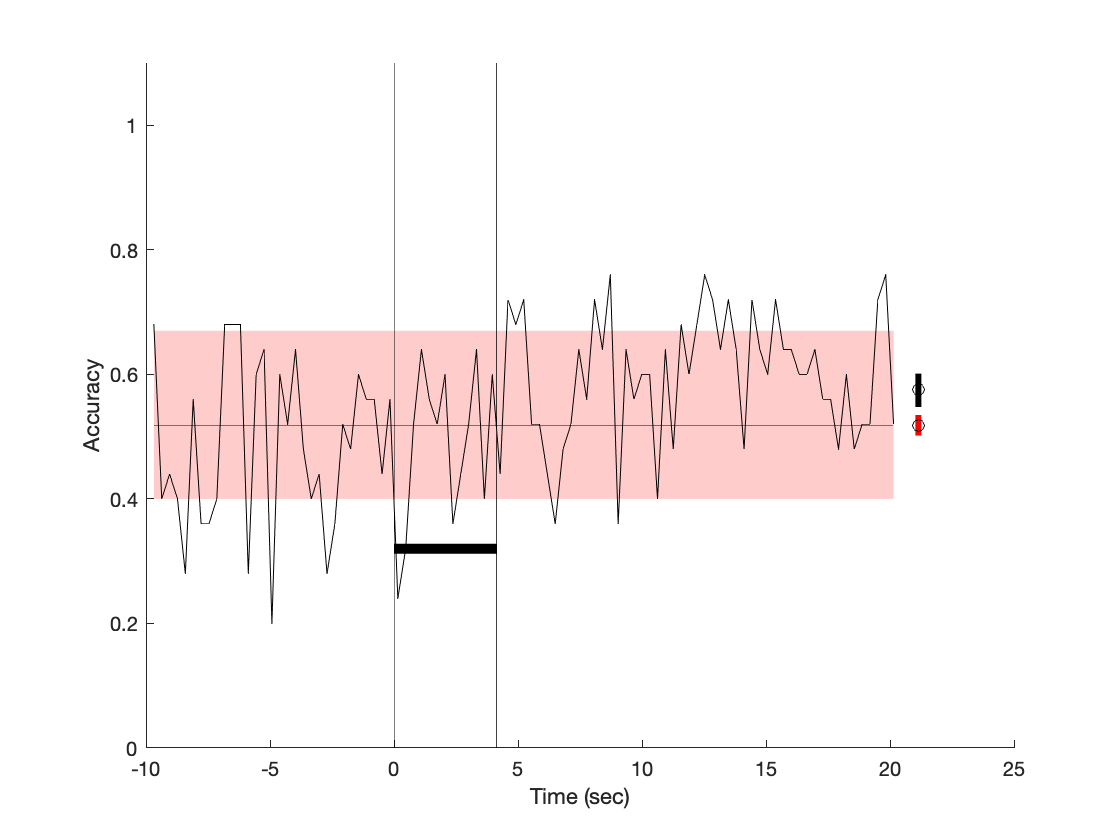

p_threshold=0.05;
MLalgo=3;
show_figures=1;
pre_perFileName = 'Results_Grin4_XY1614548423_Z0_Co-1_fixed_MC_batch_pre_per.mat';
pre_perBatchPathName = '/Users/restrepd/Documents/Projects/SFTP/Artigo_HomeOdor/AmylAcetateAcetophenone/';
drgCaImAn_pre_per_to_LDA_fsdz(pre_perBatchPathName, pre_perFileName,p_threshold,MLalgo,show_figures);

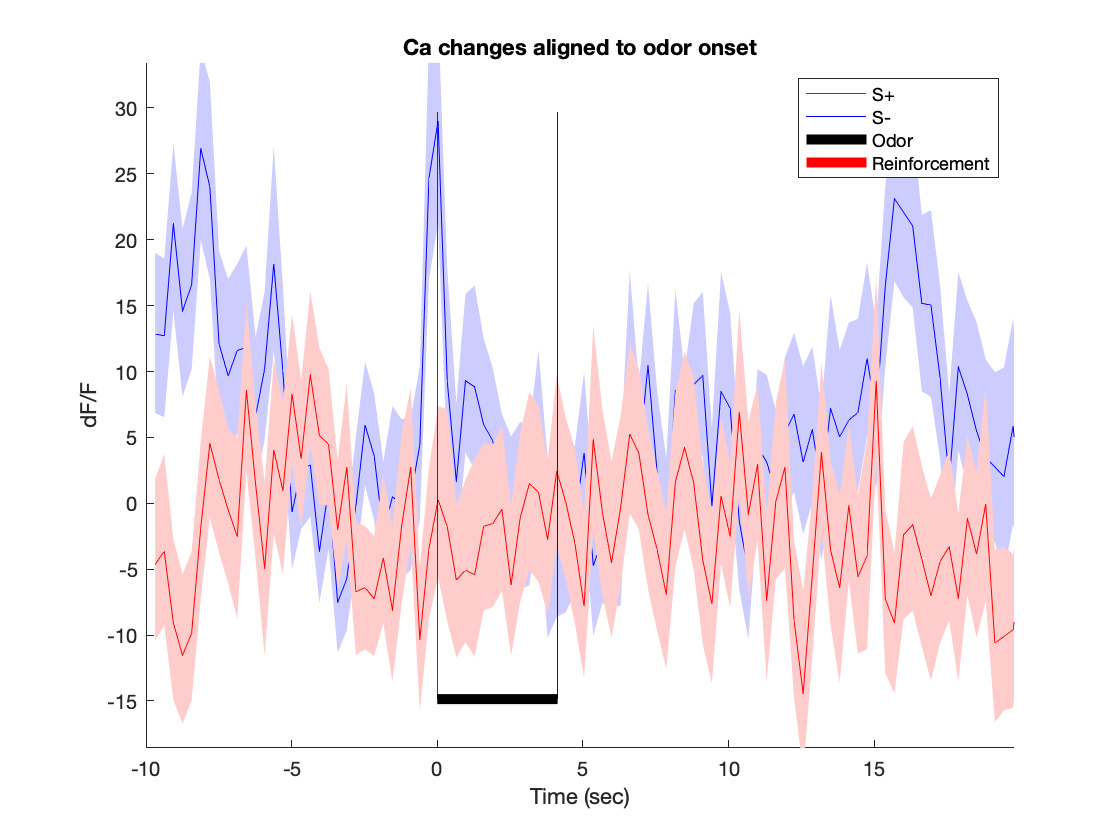

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 7
              Cluster: 

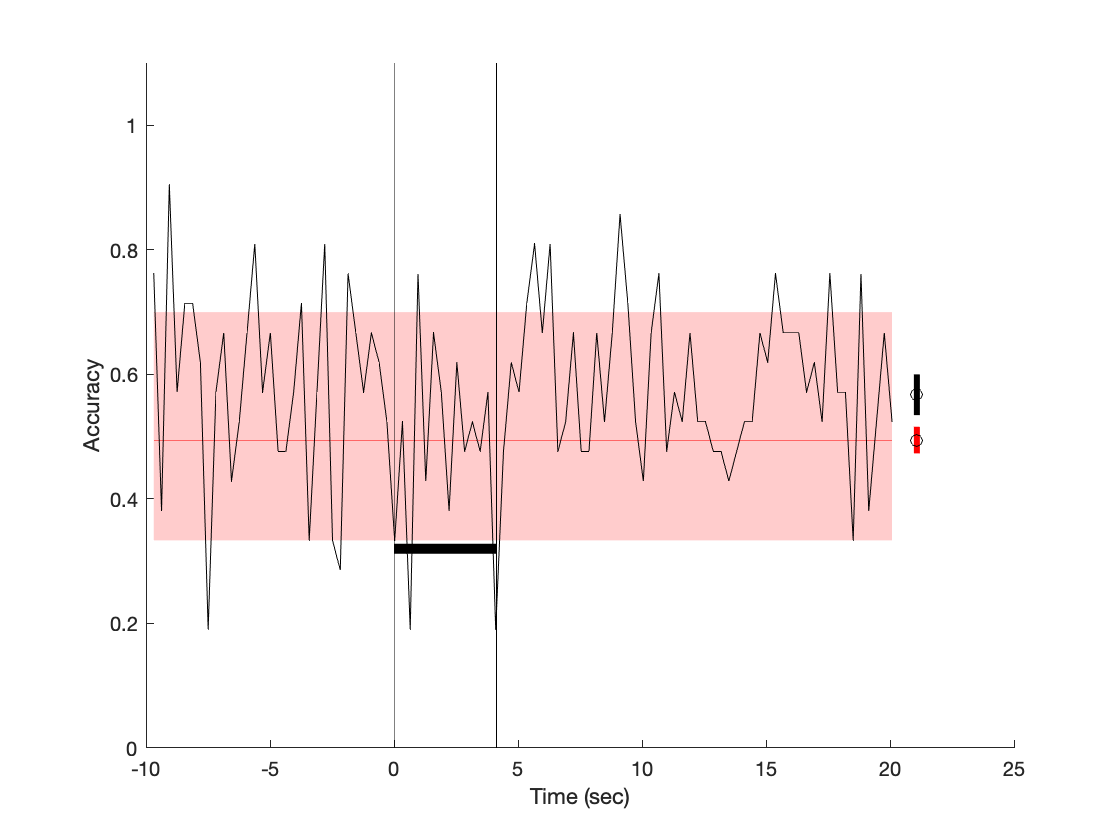

p_threshold=0.05;
MLalgo=3;
show_figures=1;
pre_perFileName = '20210308_Grin4_fsds_Amyl_Aceto_batch_pre_per.mat';
pre_perBatchPathName = '/Users/restrepd/Documents/Projects/SFTP/Artigo_HomeOdor/AmylAcetateAcetophenone/';
drgCaImAn_pre_per_to_LDA_fsdz(pre_perBatchPathName, pre_perFileName,p_threshold,MLalgo,show_figures);

Then I run the two files as a group:


drgCaImAn_batch_pre_per_to_LDA_fsdz run for drgCaImAn_LDAfsdz_choices_test_05242021.m


ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 7
              Cluster: 

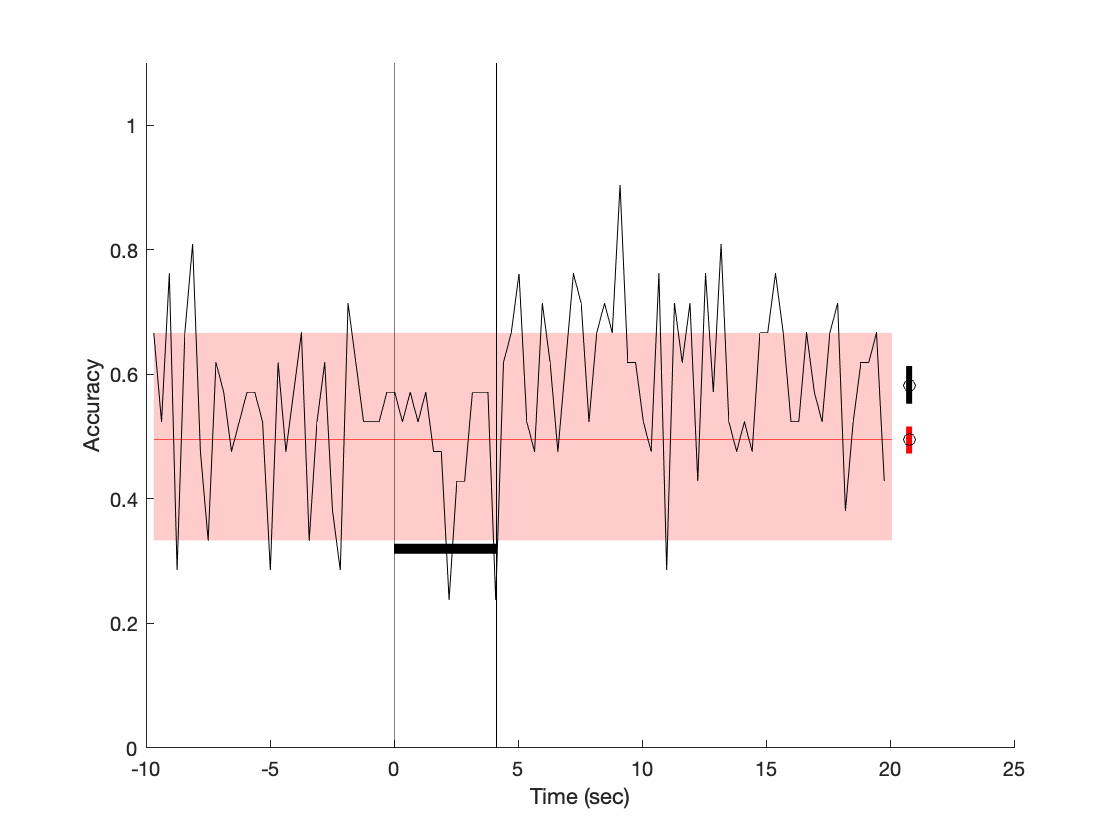

Total processing time 9.594943e+00 hours


%This is run with drgCaImAn_LDAfsdz_choices_test_05242021
drgCaImAn_batch_pre_per_to_LDA_fsdz('/Users/restrepd/Documents/Projects/SFTP/','drgCaImAn_LDAfsdz_choices_test_05242021.m')